# Simulazione Veicolo Autobilanciato - gruppo Calegari

## Setup iniziale dell'ambiente

clear
clc
digits(4)

%load('WS_VAB_wb_0.mat','A','B','C','D','r');
load('WS_VAB_wb_0_5.mat','A','B','C','D','r','J_r');
load('Gains.mat','K_c')

## Costanti del motore

Definizione delle costanti necessarie alla modellizzazione del comportamento del motore.

k_t = 0.1; % Costante di coppia [Nm/A]
R = 0.13; % Resistenza interna del motore[ohm]
L = 0.10e-3; % Induttanza del motore [H]
tau_e = L/R; % Costante di tempo elettrica [m]
tau = 0.1*22/26; % Rapporto di trasmissione
J_m_star = 3.7e-4+double(J_r)*tau^2; %Inerzia del motore ridotta all'albero [kg m^2]
I_max = 100;
fc=1000;
wc=2*pi*fc;
ti_i = tau_e;
kg_i = wc*tau_e*R; 
PI_I = kg_i*tf([ti_i,1],[ti_i,0]);

MODELLO 2

Il primo parametro che andiamo a definire rappresenta l'inerzia del rotore ridotta allìalbero motore.

Per costruzione, è presente una trasmissione a cinghia che presenta un passo 8: essendo il passo uguale per entrambe le pulegge, si ha che l'effettivo diametro delle pulegge stesse, nel calcolo del rapporto di trasmissione, viene a cadere, e quindi risulta essere sufficiente andare ad effettuare il rapporto tra il numero di denti delle pulegge:

 
$$\tau =\frac{n_{\textrm{in}\;} }{n_{\textrm{out}} }$$


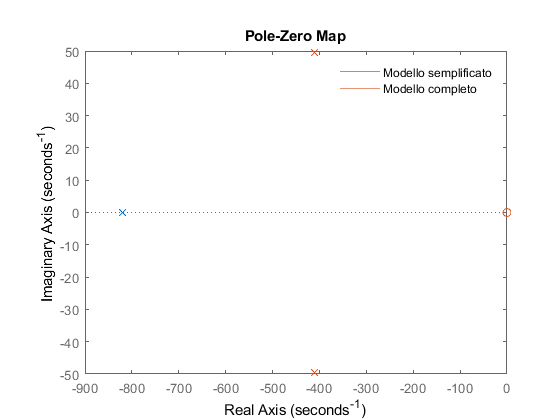

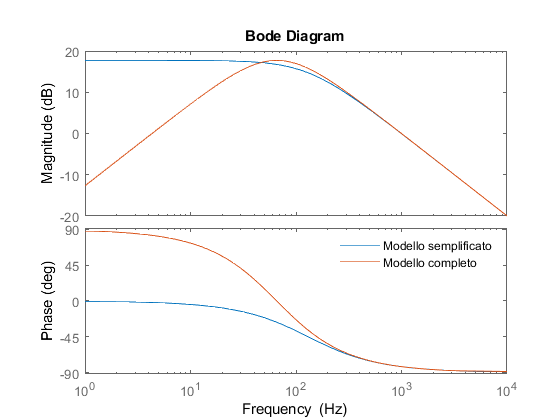

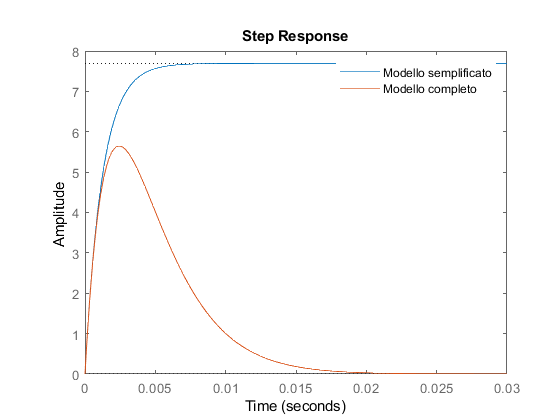

tau = 0.1*22/26;
J_rotore = double(J_r) * tau^2;
Ts = 0.0001;
showBode = true;
motor = ConfigDCMotor(1, J_rotore, showBode);


PI_I =
 
  0.001216 s + 0.9965
  -------------------
       0.00122 s
 
Continuous-time transfer function.


PI_I_d =
 
  1.037 z - 0.9557
  ----------------
       z - 1
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



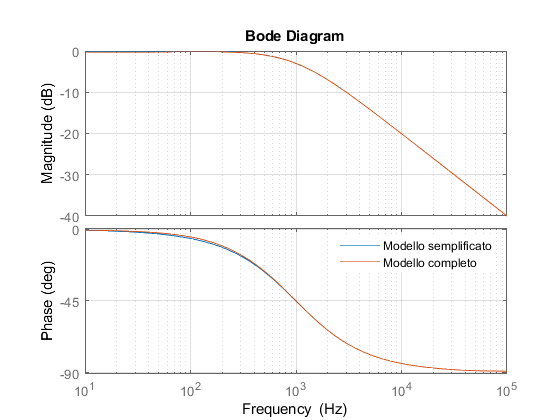

currentClosedLoop = CurrentLoop(motor, showBode, Ts);

motor_selection = 0;

## Conversioni matrici state space

A_real = double(A);
B_real = double(B);
C_real = double(C);
D_real = double(D);

## Simulazione

### Condizioni iniziali e altri parametri

% Initial condition for open loop model
x_0 = [0; 0; 4 * pi / 180; 0];
phi_iniziale = x_0(1);
phi_p_iniziale = x_0(2);
theta_iniziale = x_0(3);
theta_p_iniziale = x_0(4);
phi_p_setpoint = 15;
t_end = 20;
r_simulazione = double(r);
m_c_simulazione = double(70); % Vale solo nel non lineare alpha
k_simulazione_continua = K_c;


control_on = 1;

## Simulazione con controllo

### Sistema lineare


disp('Closed loop');

Closed loop


disp('Linear system');

Linear system


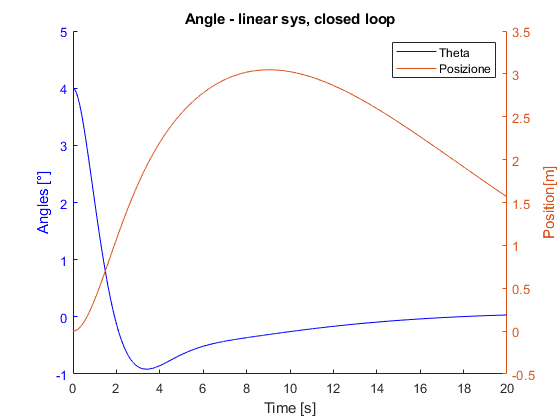

simOut = sim('VAB_Linear');
completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torqueRequested = simOut.torqueRequested;
actualTorque = simOut.actualTorque;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;
figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - linear sys, closed loop')
hold off

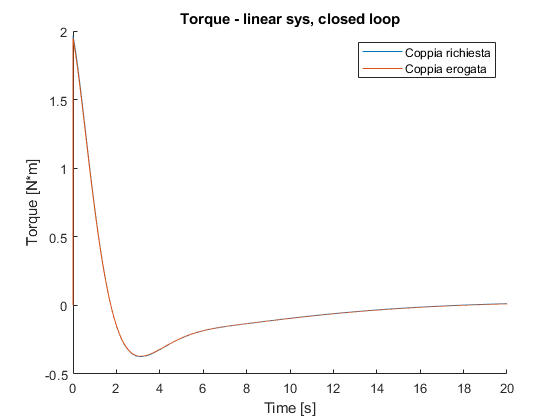

figure
hold on
plot(tout, [torqueRequested,actualTorque])
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - linear sys, closed loop')
legend('Coppia richiesta', 'Coppia erogata');
hold off

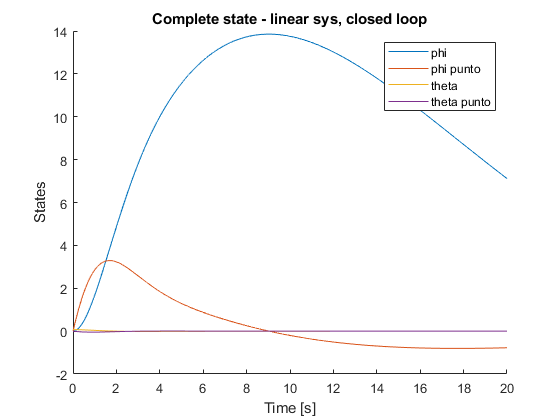


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - linear sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off

### Sistema non lineare

disp('Non linear system');

Non linear system


simOut = sim('VAB_non_linear.slx');

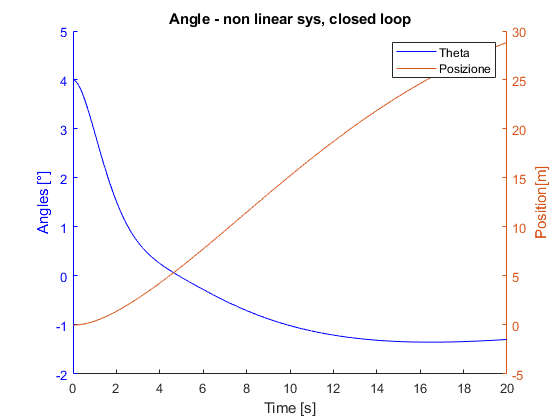

completeState = simOut.completeState;
out = simOut.Output;
thetaClamped = simOut.theta_Clamped;
phiClamped = simOut.phi_Clamped;
torqueRequested = simOut.torqueRequested;
actualTorque = simOut.actualTorque;
tout = simOut.tout;
posizione = phiClamped*r_simulazione;

figure
hold on
plot(tout, thetaClamped,'b')
xlabel('Time [s]')
yyaxis left
ylabel('Angles [°]')
yyaxis right
ylabel('Position[m]')
plot(tout, posizione)
legend('Theta','Posizione');
ax = gca;
ax.YAxis(1).Color = 'b';
title('Angle - non linear sys, closed loop')

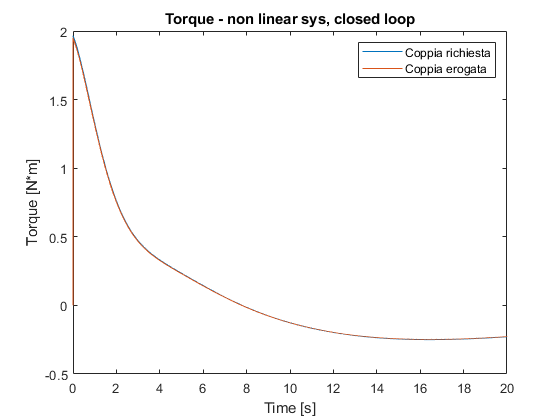

figure
%[torqueRequested,actualTorque]
plot(tout, [torqueRequested,actualTorque])
xlabel('Time [s]')
ylabel('Torque [N*m]')
title('Torque - non linear sys, closed loop')
legend('Coppia richiesta', 'Coppia erogata');
hold off

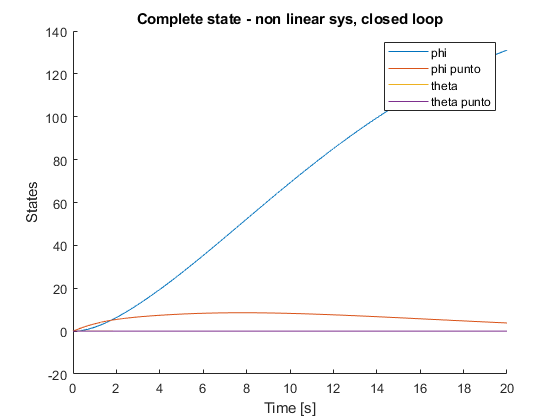


figure
hold on
plot(tout, completeState)
xlabel('Time [s]')
ylabel('States')
title('Complete state - non linear sys, closed loop')
legend('phi', 'phi punto', 'theta', 'theta punto');
hold off

clearvars ax

NB: State needs to be defined in rad!

%call_plot(completeState * pi / 180);

## Sistema in anello aperto

### Sistema Lineare

% disp('Open loop');
% disp('Linear system');
% control_on = 0;
% simOut = sim('VAB_Linear');
% completeState = simOut.completeState;
% out = simOut.Output;
% thetaClamped = simOut.theta_Clamped;
% phiClamped = simOut.phi_Clamped;
% torque = simOut.TorqueFeeded;
% tout = simOut.tout;
% posizione = phiClamped*r_simulazione;
% 
% figure
% hold on
% plot(tout, thetaClamped,'b')
% xlabel('Time [s]')
% yyaxis left
% ylabel('Angles [°]')
% yyaxis right
% ylabel('Position[m]')
% plot(tout, posizione)
% legend('Theta','Posizione');
% ax = gca;
% ax.YAxis(1).Color = 'b';
% title('Angle - linear sys, open loop')
% hold off
% 
% 
% figure
% hold on
% plot(tout, completeState)
% xlabel('Time [s]')
% ylabel('States')
% title('Complete state - linear sys, open loop')
% legend('phi', 'phi punto', 'theta', 'theta punto');
% hold off
% 
% % for i=1:size(completeState,1)
% %     call_plot(completeState(i,:))
% % end

### Sistema non lineare

% disp('Non linear system');
% simOut = sim('VAB_non_linear.slx');
% completeState = simOut.completeState;
% out = simOut.Output;
% thetaClamped = simOut.theta_Clamped;
% phiClamped = simOut.phi_Clamped;
% torque = simOut.TorqueFeeded;
% tout = simOut.tout;
% posizione = phiClamped*r_simulazione;
% 
% figure
% hold on
% plot(tout, thetaClamped,'b')
% xlabel('Time [s]')
% yyaxis left
% ylabel('Angles [°]')
% yyaxis right
% ylabel('Position[m]')
% plot(tout, posizione)
% legend('Theta','Posizione');
% ax = gca;
% ax.YAxis(1).Color = 'b';
% title('Angle - non linear sys, open loop')
% hold off
% 
% figure
% hold on
% plot(tout, completeState)
% xlabel('Time [s]')
% ylabel('States')
% title('Complete state - non linear sys, open loop')
% legend('phi', 'phi punto', 'theta', 'theta punto');
% hold off